TrendTradingMainScript

Preparation

clear
    
tic

Read data

load TrendTrading.mat IndexTT PriceTTFullRaw VolumeTTFullRaw
IndexTT ;
PriceTTFullRaw ;
VolumesTTFullRaw = VolumeTTFullRaw ;

Clean data

PriceTTFull = fillmissing (PriceTTFullRaw, "previous") ;
PriceTTFull = fillmissing (PriceTTFull, "next") ;

VolumesTTFullRawVars = VolumesTTFullRaw.Variables ;
VolumesTTFullRawVarsIdx = VolumesTTFullRawVars < 100';
VolumesTTFullRawVars (VolumesTTFullRawVarsIdx) = NaN ;
VolumesTTFullRaw.Variables = VolumesTTFullRawVars ;
VolumesTTFull = fillmissing (VolumesTTFullRaw, "previous") ;


Split dataset into IST and OST

nRowFull = int64 (size (PriceTTFull,1)) ;
nRowISTproportion = 80/100 ;  % Proportion of dataset to be in Sample Dataset
nRowIST = int64(round(nRowISTproportion*nRowFull)) ;
nRowOST = round (nRowFull-nRowIST) ;

% IST dataset
PricesIST = (PriceTTFull (1:nRowIST, :)) ;
VolumesIST = (VolumesTTFull (1:nRowIST, :)) ;

% OST dataset
PricesOST = (PriceTTFull (nRowIST:end, :)) ;
VolumesOST = (VolumesTTFull (nRowIST:end, :)) ;


Backtest

% Backtest input

% x = [10^3 10^9 10 -10 20 10^6 20 30 25 5 40 -8 4]
x = [10^3	10^9	100	80	200	10^15	10^15	200	80	200	200	80	200]

x =        1000.00 1000000000.00        100.00         80.00        200.00 1000000000000000.00 1000000000000000.00        200.00         80.00        200.00        200.00         80.00        200.00


summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn               0.00       
    SharpeRatio                NaN       
    Volatility                0.00       
    AverageTurnover           0.00       
    MaxTurnover               0.00       
    AverageReturn             0.00       
    MaxDrawdown               0.00       
    AverageBuyCost            0.00       
    AverageSellCost           0.00       


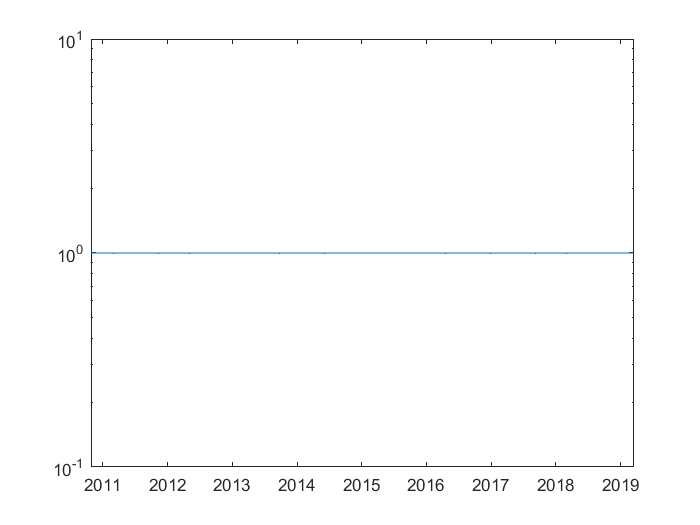

EndCumSumVar =          -1.00


TradingPeriod =           8.40


CAGR =              0


SharpeRatio =            NaN


Sortino =            NaN


Elapsed time is 11.374196 seconds.


SharpeRatio =          -1.00



% lb = [1	1	1	-50	1	1	1	1	-50	1	1	-50	1] ;
% ub = [10^15	10^15	200	80	200	10^15	10^15	200	80	200	200	80	200] ;

% LowSkipValTreshCorrection = x(1) ; 
% MinValue = x(2) ;
% MomContDays = x(3) ; 
% MomContRetTrheshold = x(4) ; 
% LowLiquidDays = x(5) ;
% LowLiquidThreshold = x(6) ;
% LiquidSurgThreshold = x(7) ;
% MomMainDays = x(8) ;
% MomMainRetThreshold = x(9) ;
% PostSignalBufferDays = x(10) ;
% StopLossLookbackWindSz = x(11) ;
% StopLossThreshold = x(12) ;
% RebalanceFreq = x(13) ;

% Call the function
SharpeRatio = TrendTradingFcnMultiVarSharpe (x, PricesIST, VolumesIST) 

Optimize parameters in IST

options = optimoptions ('ga', 'UseParallel', true, 'UseVectorized', ...
    false, "FunctionTolerance", 0.05, "MaxGenerations",20, 'MaxTime', 60*5)

options =   ga options:

   Set properties:
               FunctionTolerance: 0.05
                  MaxGenerations: 20.00
                         MaxTime: 300.00
                     UseParallel: 1
                   UseVectorized: 0

   Default properties:
             ConstraintTolerance: 0.00
                     CreationFcn: @gacreationuniform
                    CrossoverFcn: @crossoverscattered
               CrossoverFraction: 0.80
                         Display: 'final'
                      EliteCount: '0.05*PopulationSize'
                    FitnessLimit: -Inf
               FitnessScalingFcn: @fitscalingrank
                       HybridFcn: []
         InitialPopulationMatrix: []
          InitialPopulationRange: []
             InitialScoresMatrix: []
             MaxStallGenerations: 50.00
                    MaxStallTime: Inf
                     MutationFcn: {@mutationgaus

options = optimoptions(options,'PlotFcn',{@gaplotbestf,@gaplotstopping})

options =   ga options:

   Set properties:
               FunctionTolerance: 0.05
                  MaxGenerations: 20.00
                         MaxTime: 300.00
                         PlotFcn: {@gaplotbestf  @gaplotstopping}
                     UseParallel: 1
                   UseVectorized: 0

   Default properties:
             ConstraintTolerance: 0.00
                     CreationFcn: @gacreationuniform
                    CrossoverFcn: @crossoverscattered
               CrossoverFraction: 0.80
                         Display: 'final'
                      EliteCount: '0.05*PopulationSize'
                    FitnessLimit: -Inf
               FitnessScalingFcn: @fitscalingrank
                       HybridFcn: []
         InitialPopulationMatrix: []
          InitialPopulationRange: []
             InitialScoresMatrix: []
             MaxStallGenerations: 50.00
                    


FitnessFunction = @(x) TrendTradingFcnMultiVarSharpe (x, PricesIST, VolumesIST) ;
nvars = 13 ;
lb = [1	1	1	-50	1	1	1	1	-50	1	1	-50	1] ;
ub = [10^15	10^15	200	80	200	10^15	10^15	200	80	200	200	80	200] ;

% ConstraintFunction = @nlconGA ;
IntCon = 1:nvars ;

[x, fval] = ga(FitnessFunction, nvars, [], [], [], [], lb, ub, [],IntCon, options )


summaryTable =

  9x1 table

                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxDrawdown                 0        
    AverageBuyCost              0        
    AverageSellCost             0        


EndCumSumVar =

    -1


TradingPeriod =

    8.3973


CAGR =

     0


SharpeRatio =

   NaN


Sortino =

   NaN

Elapsed time is 28.186368 seconds.

summaryTable =

  9x1 table

                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn             

Error using TrendTradingMainScript>@(x)TrendTradingFcnMultiVarSharpe(x,PricesIST,VolumesIST) (line 59)
Error: File: C:\Users\jd\MATLAB\Projects\ScientificTradeMatlab\OptimMultiVar\TrendTradingFcnMultiVarSharpe.mlx Line: 269 Column: 26
Incorrect use of '=' operator. To compare values for equality, use '=='. To specify name value arguments, check that name is a valid identifier with no quotes.

Error in 


xInputOptimized = x ;

Apply the parameters into OST

xInputOptimized;
SharpeRatioOptimized = TrendTradingFcnMultiVarSharpe (xInputOptimized, PricesIST, VolumesIST) 


Examine OST

Closing

toc